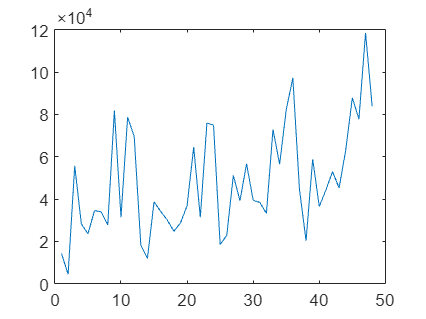

%% Load data & Formulate origin and fitting series in .txt
load("..\data\ComparedSOTA_Dataset.mat")
time=1:48;
plot(time,MonthlySales)

[xData, yData] = prepareCurveData( time, MonthlySales );

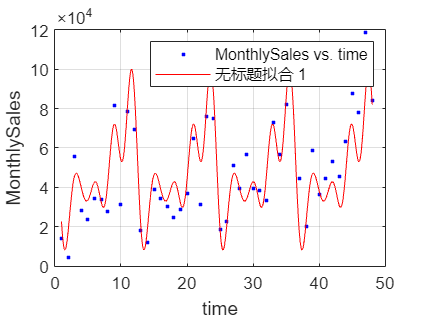

ft = fittype( 'fourier5' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0 0 0 0 0 0 0 0 0 0 0 0.534739175079114];
[fitresult, gof] = fit( xData, yData, ft, opts );
figure( 'Name', "fourier5" );
h = plot( fitresult, xData, yData );
legend( h, 'MonthlySales vs. time', 'fourier5', 'Location', 'NorthEast', 'Interpreter', 'none' );
xlabel( 'time', 'Interpreter', 'none' );
ylabel( 'MonthlySales', 'Interpreter', 'none' );
grid on

y_fit = feval(fitresult, xData);
dlmwrite('X:\05_Data\pythonProject\DTW-LSTM\data\dateSalesFit.txt', y_fit, 'delimiter', '\t', 'precision', 6);
dlmwrite('X:\05_Data\pythonProject\DTW-LSTM\data\dateSales.txt', MonthlySales, 'delimiter', '\t', 'precision', 6);

%% When data has processed, employ the next preprocessing of the series
load("X:\05_Data\pythonProject\DTW-LSTM\result\processedTrainDataset.mat")
trainPercent = 7/8;
TrainLimit = 42;
delta = 6;
data = Processed;
for i = 1 : delta
    data(i + TrainLimit) = MonthlySales(i + TrainLimit);
end

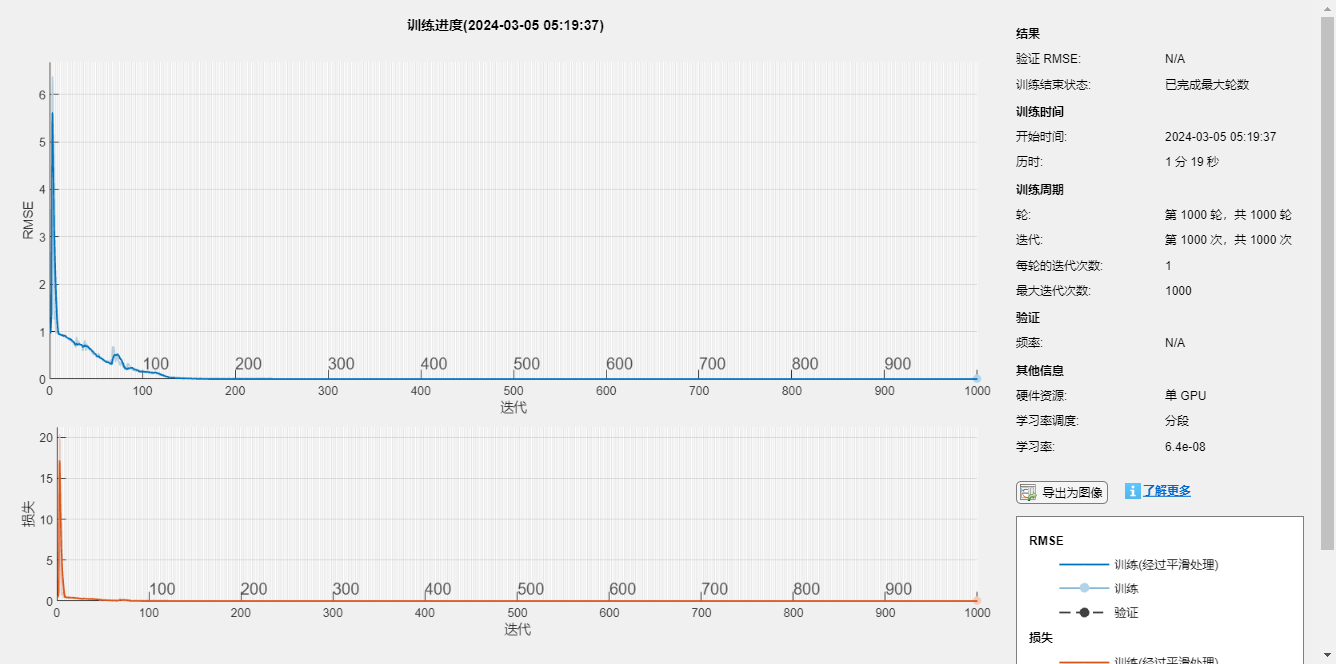

rmse = 2.1487e+04

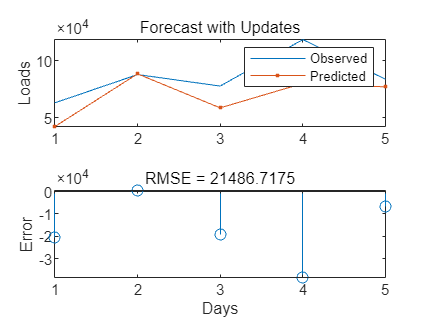

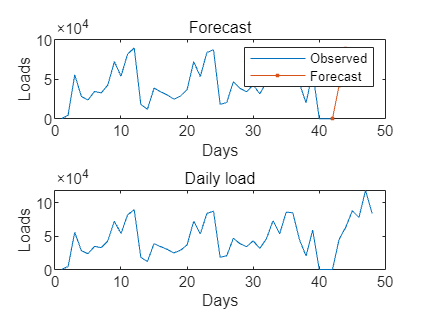

%% LSTM Process
YPred = 0;
numTimeStepsTrain = floor(trainPercent*numel(data));
dataTrain = data(1:numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1:end);
mu = mean(dataTrain);
sig = std(dataTrain);
dataTrainStandardized = (dataTrain - mu) / sig;
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 96*3;
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
options = trainingOptions('adam', ...
    'MaxEpochs',200, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');
net = trainNetwork(XTrain,YTrain,layers,options);
net = resetState(net);
net = predictAndUpdateState(net,XTrain);
dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);
YTest = dataTest(2:end);
YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
rmse = sqrt(mean((YPred-YTest).^2))
figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Loads")
title("Forecast with Updates")
subplot(2,1,2)
stem(YPred - YTest)
xlabel("Days")
ylabel("Error")
title("RMSE = " + rmse)
figure
subplot(2,1,1)
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[data(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Days")
ylabel("Loads")
title("Forecast")
legend(["Observed" "Forecast"])
subplot(2,1,2)
plot(data)
xlabel("Days")
ylabel("Loads")
title("Daily load")

%% Alignment of the last errors may require manual action
YReal = 0;
for i = 1 : delta-1
    YReal(i) = data(i + TrainLimit + 1);
end

errors = YPred - YReal;
MAE = mean(abs(errors))

MAE = 1.7089e+04

SSE = sum(errors.^2)

SSE = 2.3084e+09

RMSE = sqrt(mean(errors.^2))

RMSE = 2.1487e+04

MAPE = mean(abs(errors) ./ max(abs(YReal), eps)) * 100

MAPE = 19.6786